# APV Ensmeble Training

clear;
close all;
bdclose('all');
addpath('/home/momentumlab/Documents/git/AI-CPS-Ensemble/APV/model')
addpath('/home/momentumlab/Documents/git/AI-CPS-Ensemble/APV/DRL_training/trained_agent')
addpath('/home/momentumlab/Documents/git/AI-CPS-Ensemble/APV/abstraction/')

## Environment Setup

Ts = 0.1;
Ts_sample = 0.1;
Tf = 50;
freeSpotIndex = 32;
faceDirection = "south";    % parked car faces north or south
xRef = createReferenceTrajectory(Ts,Tf,freeSpotIndex);
map = ParkingLotEnvironment(freeSpotIndex,"Route",xRef);
egoInitialPose = [40 -55 pi/2];
egoTargetPose = createTargetPose(map,freeSpotIndex,faceDirection);
autoParkingValetParams3D
createMPCForParking3D;

nObs = 16;
nAct = 1;
doTraining = true;

## Load Constitutional Controllers

myFolder = "/home/momentumlab/Documents/git/AI-CPS-Ensemble/APV/DRL_training/trained_agent";
% check if folder path is valid
if ~isfolder(myFolder)
    errorMessage = sprintf('Error: The following folder does not exist:\n%s', myFolder);
    uiwait(warndlg(errorMessage));
    return;
end

% load all .MAT files under determined folder
filePattern = fullfile(myFolder, '*.mat');
matFiles = dir(filePattern);
[fileNumber, ~]= size(matFiles);

% get selected DRL agents
matFiles = struct2cell(matFiles);
allAgentName = matFiles(1,:);
allAgentName = convertCharsToStrings(allAgentName)';
allAgentName = [allAgentName(3:end-1)];

% load trained RL controllers
rlAgentName = allAgentName;

agent1 = load(rlAgentName(1)).saveAgent.agent;
agent2 = load(rlAgentName(2)).saveAgent.agent;
agent3 = load(rlAgentName(3)).saveAgent.agent;
agent4 = load(rlAgentName(4)).saveAgent.agent;
agent5 = load(rlAgentName(5)).saveAgent.agent;
agent6 = load(rlAgentName(6)).saveAgent.agent;
agent7 = load(rlAgentName(7)).saveAgent.agent;
agent8 = load(rlAgentName(8)).saveAgent.agent;
agent9 = load(rlAgentName(9)).saveAgent.agent;

numRL = 9;                          % num of RL controllers
rewardWeights = [2, 0.5, 0.05];     % rewardWeights for candidate agents
isTerminate = false;                % candidate agents do not terminate
predIndexVector = 3;                % only take the total reward as the prediction result

% load abstracted MDP
abstractMDP = load("APV_abstract_model").abModel;
actionUB = abstractMDP.actionUB;
rewardUB1 = abstractMDP.rewardUB_1;
rewardUB2 = abstractMDP.rewardUB_2;
rewardToIndex = abstractMDP.rewardToIndexTable;
tranTable = abstractMDP.tranTable;
stateTable = tranTable(:,1);
actionTable = tranTable(:,2);

## DRL Obs/Act configuration

Creating an environment model includes action, obervation

**Observation**: 

- +16 original obs

- +9 Predictions

**Action**: Fuel injected, [0.13, 1.66]

% if use prediction as additional features
isPred = false;

if isPred
% observation
    obsInfo = rlNumericSpec([25 1],...
        'LowerLimit', -inf*ones(25,1),...
        'UpperLimit', inf*ones(25,1));
    obIsnfo.Name = 'observations';
    obsInfo.Description = 'state, predicted semantics';
    numObservations = obsInfo.Dimension(1);
else
    obsInfo = rlNumericSpec([16 1],...
        'LowerLimit', -inf*ones(16,1),...
        'UpperLimit', inf*ones(16,1));
    obIsnfo.Name = 'observations';
    obsInfo.Description = 'state';
    numObservations = obsInfo.Dimension(1);
end

% action
actInfo = rlFiniteSetSpec([1 2 3 4 5 6 7 8 9]);
actInfo.Name = 'controller selection';
numActions = actInfo.Dimension(1);

mdl = 'APV_ensemble_training';
agentblk = [mdl, '/Controller/RL Controller/ensemble_RL'];

% Build the environment interface object.
env = rlSimulinkEnv(mdl,agentblk,obsInfo,actInfo);

env.ResetFcn = @autoParkingValetResetFcn3D;

% Fix the random generator seed for reproducibility
% rng(0);

## DRL Agent Configuration

Create a network to be used as underlying critic approximator

criticNetwork = [
    featureInputLayer(numObservations,'Normalization','none','Name','observation')
    fullyConnectedLayer(64,'Name','CriticStateFC1')
    reluLayer('Name','CriticRelu1')
    fullyConnectedLayer(128,'Name','CriticStateFC2')
    reluLayer('Name','CriticCommonRelu1')
    fullyConnectedLayer(256,'Name','CriticCommonFC1')
    reluLayer('Name','CriticCommonRelu2')
    fullyConnectedLayer(128,'Name','CriticCommonFC2')
    reluLayer('Name','CriticCommonRelu3')
    fullyConnectedLayer(64,'Name','CriticCommonFC3')
    reluLayer('Name','CriticCommonRelu4')
    fullyConnectedLayer(1,'Name','CriticOutput')];

% convert the network to a dlnetwork object
criticNetwork = dlnetwork(criticNetwork);

% create critic based on the network approximator
critic = rlValueFunction(criticNetwork,obsInfo,'UseDevice','cpu');

% create a network to be used as underlying actor approximator
actorNetwork = [
    featureInputLayer(prod(obsInfo.Dimension),'Normalization','none','Name','observation')
    fullyConnectedLayer(32,'Name','ActorFC1')
    reluLayer('Name','ActorRelu1')
    fullyConnectedLayer(64,'Name','ActorFC2')
    reluLayer('Name','ActorRelu2')
    fullyConnectedLayer(128,'Name','ActorFC3')
    reluLayer('Name','ActorRelu3')
    fullyConnectedLayer(64,'Name','ActorFC4')
    reluLayer('Name','ActorRelu4')
    fullyConnectedLayer(length(actInfo.Elements),'Name','ActorFC5')                       
    softmaxLayer('Name','actionProb')];

actor  = rlDiscreteCategoricalActor(actorNetwork,obsInfo,actInfo);

**Noise model:**

- It is common to set `StandardDeviation*sqrt(Ts)` to a value between 1% and 10% of your action rang.

- To increase exploration, you can reduce the `StandardDeviationDecayRate`.

% Optimization options for actors and critics
myCriticOpts=rlOptimizerOptions(...
    'LearnRate',2e-3,...
    'GradientThreshold',1,...
    'GradientThresholdMethod',"l2norm",...
    'L2RegularizationFactor', 1e-3,...
    'Optimizer',"adam");

myActorOpts=rlOptimizerOptions(...
    'LearnRate',1e-3,...
    'GradientThreshold',1,...
    'GradientThresholdMethod',"l2norm",...
    'L2RegularizationFactor', 1e-3,...
    'Optimizer',"adam");

agentOptions = rlACAgentOptions(...
    'CriticOptimizerOptions', myCriticOpts,...
    'ActorOptimizerOptions',myActorOpts,...
    'SampleTime',Ts,...
    'NumStepsToLookAhead',5,...
    'EntropyLossWeight',0.01,...
    'DiscountFactor',0.99);

% agent creation
agentEnsemble = rlACAgent(actor, critic, agentOptions);

## **Training Configurations**

Change the weights distribution among subsitutional rewards

maxepisodes = 5000; 
window_length = 200;
distWeight = 1;
orientWeight = 1;
stableWeight = 0.05;
ensembleRewardWeights = [distWeight, orientWeight, stableWeight];
maxsteps = 200;
parkGain = 50;
collisionGain = -200;
lidarGain = 2;

trainOpts = rlTrainingOptions(...
    'MaxEpisodes', maxepisodes, ...
    'MaxStepsPerEpisode', maxsteps, ...
    'ScoreAveragingWindowLength',window_length, ...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue', 300,...
    'Verbose', false,...
    'Plots','training-progress',...
    'UseParallel',false);

if doTraining
    % Train the agent.
    trainingStats = train(agentEnsemble,env,trainOpts);
else
%     agent = load('preTrainedAgent.mat');
%     agent = agent.agent;
end

## Save trained agent 

Save DRL agent with training configurations, agent configurations and training progress info

isSave = false;

if isSave
    dateOfTrain = date;
    if isPred
        agentName = ['APV-ensemble-pred-revised-AC-9-RL-0-PID-', dateOfTrain(1:end-5)];
    else
        agentName = ['APV-ensemble-no-pred--AC-9-RL-0-PID-', dateOfTrain(1:end-5)];
    end
    agentName = agentName+...
        "-"+string(ensembleRewardWeights(1))+...
        "-"+string(ensembleRewardWeights(2))+...
        "-"+string(ensembleRewardWeights(3));

    saveAgent = struct('agentName', agentName, ...
                 'agent', agentEnsemble, ...
                 'rewardWeights', ensembleRewardWeights, ...
                 'ensembleMPC',[],...
                 'agentOptions', agentOptions, ...
                 'criticNetwork', criticNetwork, ...
                 'actorNetwork', actorNetwork, ...
                 'trainOpts', trainOpts);

    path = "/home/momentumlab/Documents/git/AI-CPS-Ensemble/APV/ensemble/trained_agent/";
    save(path+agentName+'.mat', "saveAgent");
    disp(agentName + ' saved')
end

APV-ensemble-no-pred--AC-9-RL-0-PID-15-Jul-1-1-0.05 saved


## Simulation & Plotting

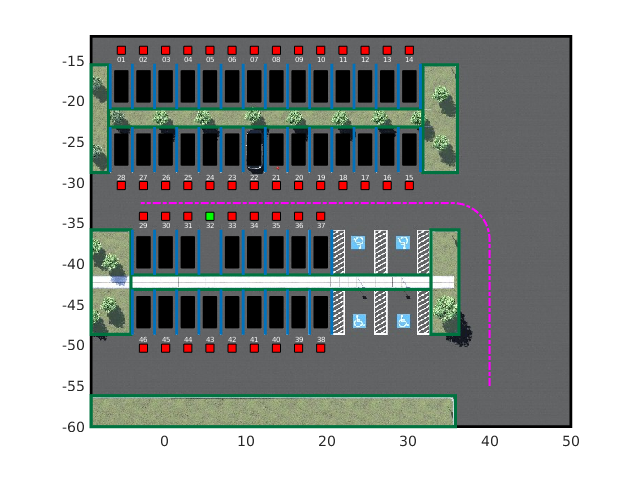

simOpts = rlSimulationOptions('MaxSteps',maxsteps,'StopOnError','on');

% get results
experiences = sim(env,agentEnsemble,simOpts);
totalReward = sum(experiences.Reward);

% extract signals from simulation results
% time = experiences.SimulationInfo.tout;
% steps = size(time);
% steps = steps(1);
x_error = experiences.SimulationInfo.logsout.getElement('x_error').Values.Data;
steps = length(x_error);
time = 1:steps;

y_error =  experiences.SimulationInfo.logsout.getElement('y_error').Values.Data;
theta_error =  experiences.SimulationInfo.logsout.getElement('theta_error').Values.Data;
steer_angle =  experiences.SimulationInfo.logsout.getElement('steer_angle').Values.Data;
lidar_min_dist =  experiences.SimulationInfo.logsout.getElement('lidar_min_dist').Values.Data;
is_parked =  experiences.SimulationInfo.logsout.getElement('is_parked').Values.Data;
is_collision =  experiences.SimulationInfo.logsout.getElement('is_collision').Values.Data;
selection =  experiences.SimulationInfo.logsout.getElement('selection').Values.Data;
% theta_error = reshape(theta_error, [steps,1]);


figure(1);

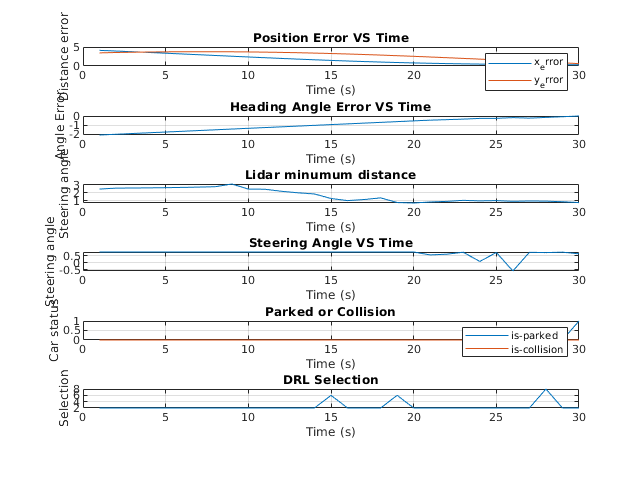

subplot(6,1,1)
plot(time,x_error, time,y_error)
title('Position Error VS Time')
legend('x_error', 'y_error')
xlabel('Time (s)') 
ylabel('Distance error') 
grid on

subplot(6,1,2)
plot(time,theta_error)
title('Heading Angle Error VS Time')
xlabel('Time (s)') 
ylabel('Angle Error') 
grid on

subplot(6,1,3)
plot(time,lidar_min_dist)
title('Lidar minumum distance')
xlabel('Time (s)') 
ylabel('Steering angle') 
grid on

subplot(6,1,4)
plot(time,steer_angle)
title('Steering Angle VS Time')
xlabel('Time (s)') 
ylabel('Steering angle') 
grid on

subplot(6,1,5)
plot(time,is_parked, time,is_collision)
title('Parked or Collision')
xlabel('Time (s)') 
legend('is-parked', 'is-collision')
ylabel('Car status') 
grid on

subplot(6,1,6)
plot(time, selection)
title('DRL Selection')
xlabel('Time (s)') 
ylabel('Selection') 
grid on

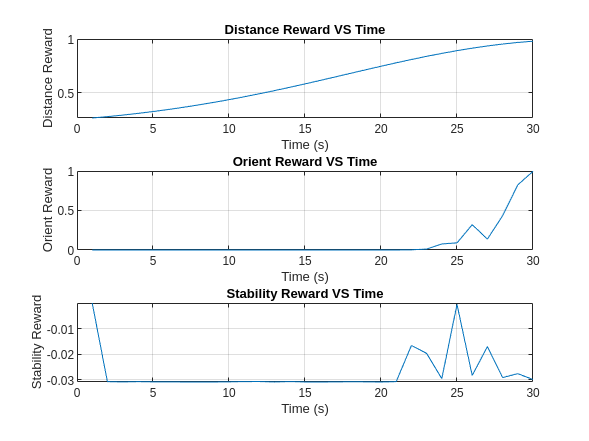

figure(2);
dist_reward =  experiences.SimulationInfo.logsout.getElement('dist_reward').Values.Data;
orient_reward =  experiences.SimulationInfo.logsout.getElement('orient_reward').Values.Data;
stable_reward =  experiences.SimulationInfo.logsout.getElement('stable_reward').Values.Data;

subplot(3,1,1)
plot(time,dist_reward)
title('Distance Reward VS Time')
xlabel('Time (s)') 
ylabel('Distance Reward') 
grid on

subplot(3,1,2)
plot(time,orient_reward)
title('Orient Reward VS Time')
xlabel('Time (s)') 
ylabel('Orient Reward') 
grid on

subplot(3,1,3)
plot(time,stable_reward)
title('Stability Reward VS Time')
xlabel('Time (s)') 
ylabel('Stability Reward') 
grid on

## Training progress info

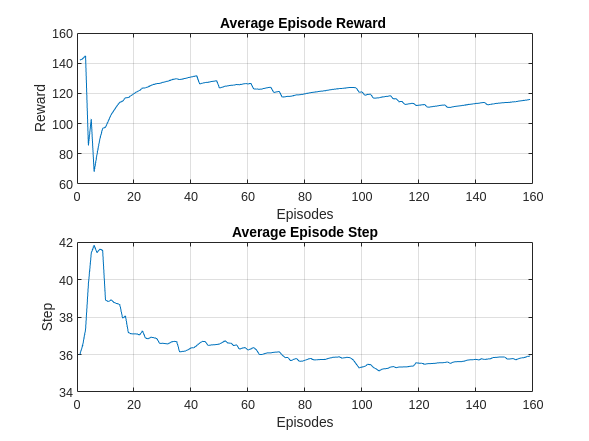

episodes = trainingStats.EpisodeIndex;
episode_reward = trainingStats.EpisodeReward;
episode_step = trainingStats.EpisodeSteps;
episode_avg_reward = trainingStats.AverageReward;
episode_avg_step = trainingStats.AverageSteps;

figure(3);
subplot(2,1,1)
plot(episodes,episode_avg_reward)
title('Average Episode Reward ')
xlabel('Episodes') 
ylabel('Reward') 
grid on

subplot(2,1,2)
plot(episodes,episode_avg_step)
title('Average Episode Step')
xlabel('Episodes') 
ylabel('Step') 
grid on